%%%% HW 2

## Problem 12c - w/ new Type III BC + GAUSS-SEIDEL

Engs105, W24 - Prof. Paulsen

### Numerical Solution

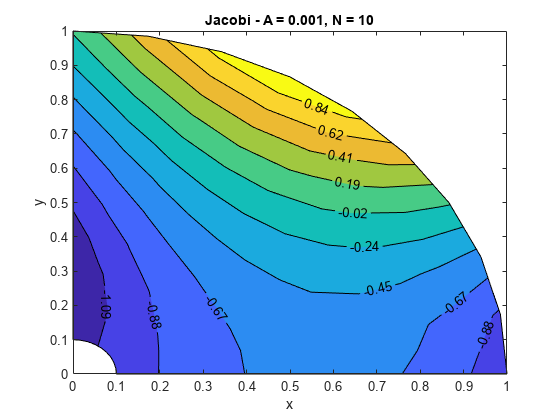

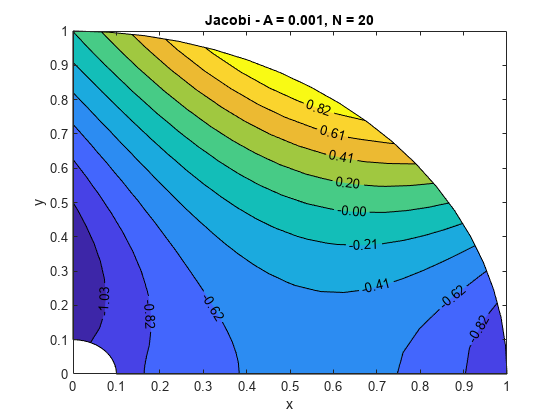

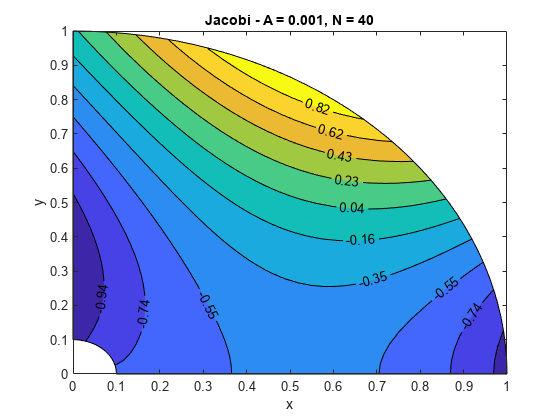

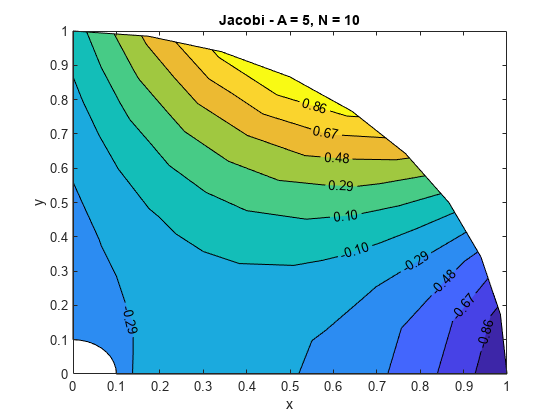

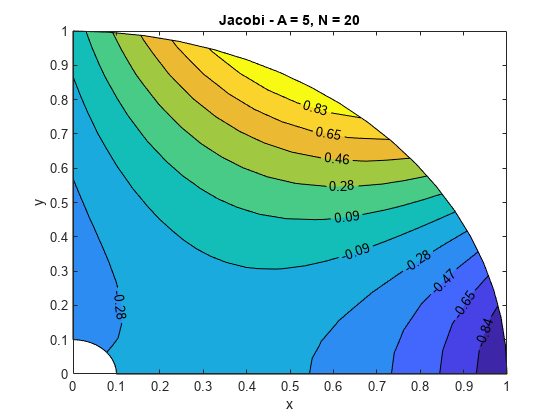

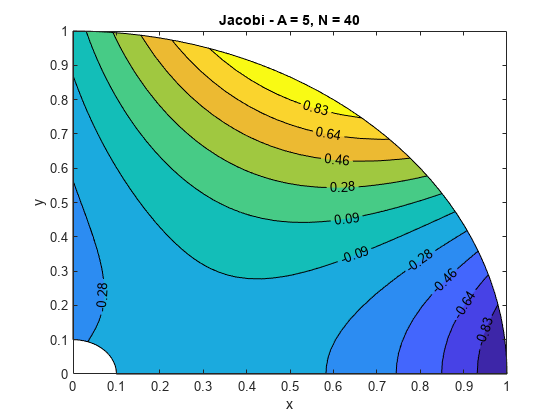

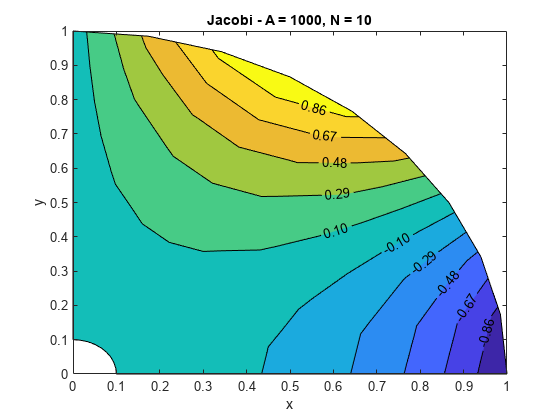

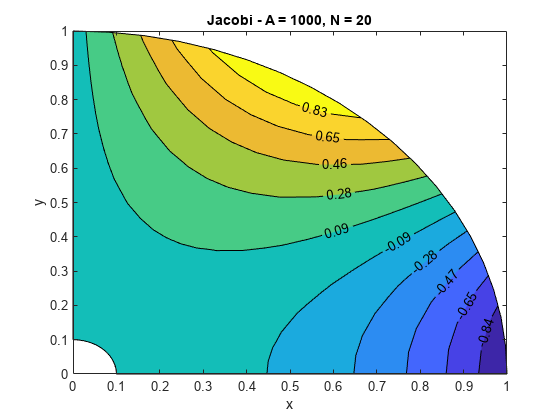

clear; close all
% Parameters
a = 0.1;
R = 1;
th_final = pi/2;

%N = 100 mesh
% Ranges for independent variables
N = 100;
r_range_100 = linspace(a, R, N);
th_range_100 = linspace(0, th_final, N);
r_mesh_100 = repmat(r_range_100, N, 1);
th_mesh_100 = repmat(th_range_100', 1, N);

ARange = [991, 5, 1000];
NRange = [10, 20, 40];

for jj = [1:length(ARange)]
    for ii = [1:length(NRange)]
    
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %% Plotting
        A = ARange(jj);
        N = NRange(ii);
       
        % Ranges for independent variables
        r_range = linspace(a, R, N);
        th_range = linspace(0, th_final, N);
        r_mesh = repmat(r_range, N, 1);
        th_mesh = repmat(th_range', 1, N);
        x_coor = r_mesh .* cos(th_mesh);
        y_coor = r_mesh .* sin(th_mesh);
        filename = ['N' num2str(N) '_A' num2str(A) '.txt'];
        X_vector = readmatrix(filename);
        
        X_mesh = reshape(X_vector, [N, N]);
        X_mesh = X_mesh';
        
        figure
        contourf(x_coor, y_coor, X_mesh, 10, "ShowText","on", "LabelFormat","%0.2f", "LabelSpacing",2000)
        hold on
        plot(zeros(N, 1), linspace(a, R, N), 'k')
        plot(linspace(a, R, N), zeros(N, 1), 'k')
        plot(a*cos(th_range), a*sin(th_range), 'k')
        plot(R*cos(th_range), R*sin(th_range), 'k')
        if A==991
            title_str = ['Jacobi - A = 0.001, N = ' num2str(N)];
            file_str = ['A991_N' num2str(N) '.png'];
        else
            title_str = ['Jacobi - A = ' num2str(A) ', N = ' num2str(N)];
            file_str = ['A' num2str(A) 'N' num2str(N) '.png'];
        end
        title(title_str)
        xlabel('x')
        ylabel('y')
        exportgraphics(gcf, file_str, 'Resolution', 300)

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %% RMS Error
        N100 = readmatrix(['..\iter' num2str(ARange(jj))]);
        N100 = reshape(N100, [100, 100]);
        N100 = N100';
        U_ana_interp = interp2(r_mesh_100, th_mesh_100, N100, r_mesh, th_mesh);

        % Store RMS error
        RMS_Errors(jj, ii) = rms(U_ana_interp - X_mesh, 'all');

    end
end

% Convert RMS_Errors matrix to table
RMS_Table = array2table(RMS_Errors, 'RowNames', string(ARange), 'VariableNames', "N" + string(NRange));

% Display the table
disp(RMS_Table);

              N10          N20         N40   
            ________    _________    ________

    991     0.044726     0.016569    0.083111
    5       0.016829     0.011125     0.03912
    1000    0.015739    0.0058801     0.00361

